# **Training CN-vs-MCIc**

Due to memory (RAM) limits instead of loading the whole Dataset we are going to process just few images (5) per time during each fold.

**Cross fold validation (for 20 fold):**

**    - Find patterns to use for Testing (index==fold) and Training (index!=fold)**

**    - Training: (until all the Training images are processed)**

- **Load 5 random RMI training images (each 121x145x121)**

- **Transform them into 500 (5*100) images 227x227x3 (~500MB)**

- **Perform Data Augmentation**

- **Train**

**    - Save trained network**

**    - Validation: (until all the Testing images are processed)**

- **Load the 5 RMI Testing images (each 121x145x121)**

- **Transform them into 500 (5*100) images 227x227x3 (~500MB)**

- **Perform Data Augmentation**

- **Use trained network to classify**

- **Add results to prediction array**

**    - Compute Accurancy**

## **1) Define the Network**

by modifing the last 3 layers of AlexNet

clear all
warning off

siz=[227 227]; % Input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers;
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Set training algorithm options**

miniBatchSize = 30;
learningRate = 1e-4;
optimizer='sgdm';
options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',30,...
    "Verbose",false,...
    "Plots","training-progress");

## **3) Load DataSet**

**Load CN.mat and MCIc.mat**

**Concatenate CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array
load CN.mat
load MCIc.mat
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
label(1:lengthClass1)=1; %Cognitive Normal = 1
label(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**Find patterns to use for Testing (Indices==fold) and Training (Indices!=fold)**

% Split dataset in Traing and Testing for this fold
fold=1;

load indices_CN-vs-MCIc.mat

trainingData=dataset(Indices~=fold);
trainingLabel=label(Indices~=fold);

testData=dataset(Indices==fold);
testLabel=label(Indices==fold);

clear dataset label

**Shuffle dataset**

Instead of shuffling directly trainingData, to save computation we create and shuffle a indicesVector

indicesVector=[1:length(trainingData)]; % Containg indices from 1 to trainingData length (~228)
indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices


## **4) Training**

**Code executed repeatedly until all the Training images are processed.**

### **4.1) Load 5 RMI training images**

setSize=5;
trainingImages=[];
label=[];   % labels of classes 
labelID=[]; % labels of ID
tmpTR=1;
for mri=1:setSize
    
    % Extract single MRI
    IMG=trainingData{indicesVector(mri)};
    
    % Transform MRI picture into 100 images 227x227x3
    IMG=mriToCNN(IMG,siz);
    trainingImages(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;
    
    
    % Return label vector the labels of the new 100 pictures
    class=trainingLabel(indicesVector(mri));
    label(tmpTR:tmpTR+size(IMG,4)-1)=class;
    
    % Remember the ID of the person
    labelID(tmpTR:tmpTR+size(IMG,4)-1)=indicesVector(mri);
    
    tmpTR=tmpTR+size(IMG,4); %Incrase by 100 the counter
    
    clear IMG;
    
end

% Because the label it's a series of 100 "1" and 100 "2"
% We shuffle again to obtain a
indicesVector=[1:length(label)];
indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices
label=label(indicesVector);
labelID=labelID(indicesVector);
trainingImages=trainingImages(:,:,:,indicesVector);
size(trainingImages)

ans =    227   227     3   500


### **4.2) Data augmentation on TrainSet**


%imageAugmenter = imageDataAugmenter( ...
        %'RandXReflection',true, ...
        %'RandXScale',[1 2], ...
        %'RandYReflection',true, ...
        %'RandYScale',[1 2],...
        %'RandRotation',[-10 10],...
        %'RandXTranslation',[0 5],...
        %'RandYTranslation', [0 5]);
    %trainingImages = augmentedImageSource(imageSize,trainingImages,categorical(y'),'DataAugmentation',imageAugmenter);
    



### **4.3) Train**

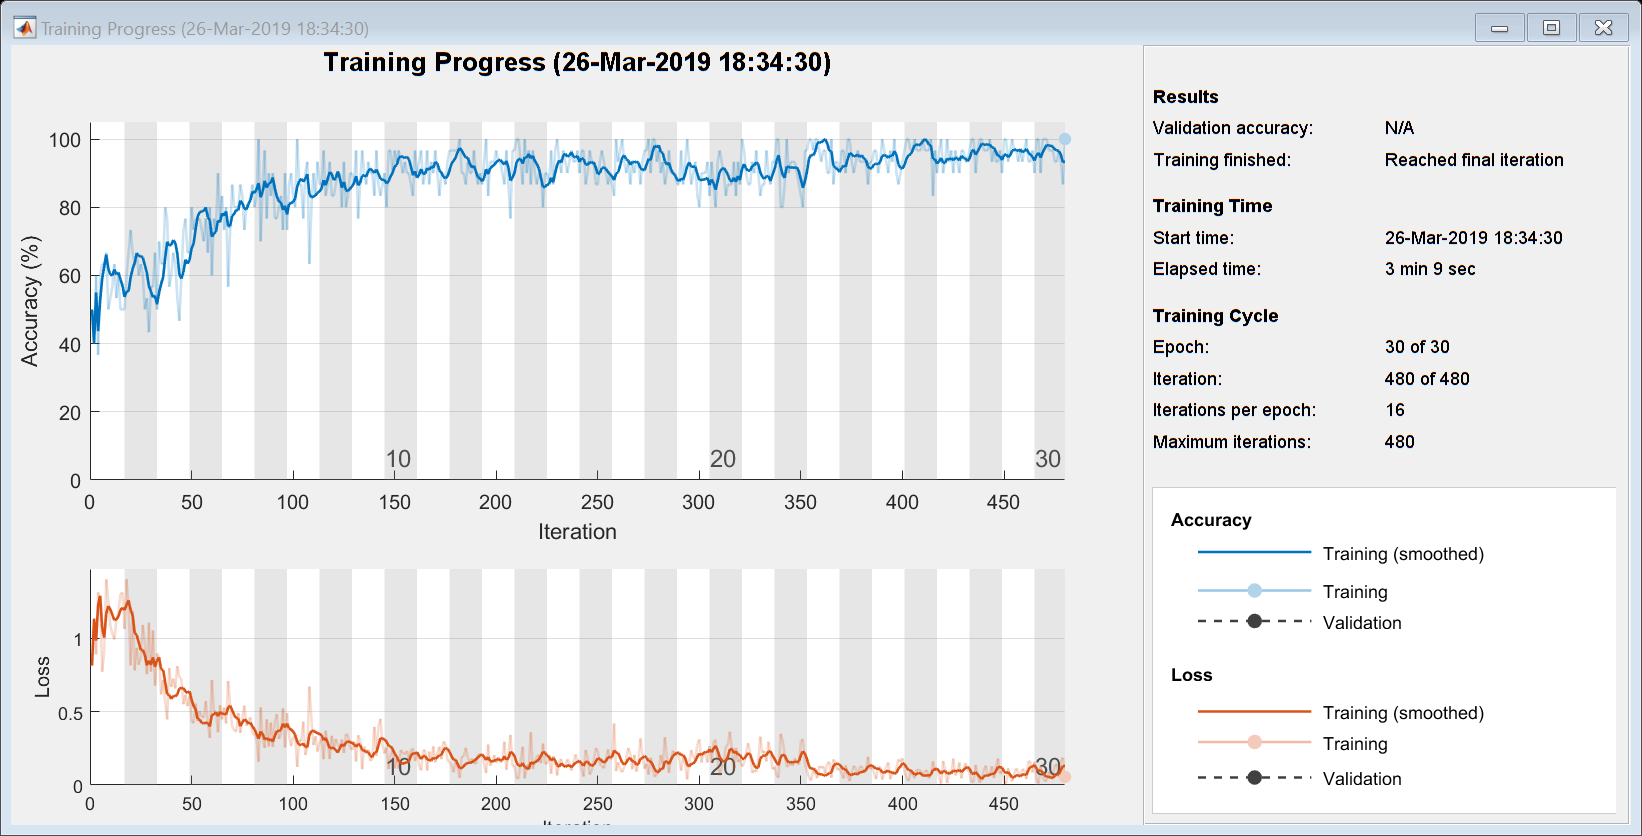

Y=categorical(label');

[trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);

info

info = struct with fields:
        TrainingLoss: [1×480 double]
    TrainingAccuracy: [1×480 double]
       BaseLearnRate: [1×480 double]


### **4.4) Save trained network**

## **5) Validation**

### **5.1) Load TestSet**

totPredictions=[];
totLabels=[];
totLabelsID=[]


totLabelsID =

     []




count=1; % Image to test
for i=1:length(testData)
    label=[];   % labels of classes 
    labelID=[]; % labels of ID
    validationImages=[];
    tmpTR=1;
    for mri=1:setSize
        % Extract single MRI
        IMG=testData{count};
        
        % Transform MRI picture into 100 images 227x227x3
        IMG=mriToCNN(IMG,siz);
        validationImages(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;
        
        % Return label vector the labels of the new 100 pictures
        class=testLabel(count);
        label(tmpTR:tmpTR+size(IMG,4)-1)=class;
        
        % Remember the ID of the person
        labelID(tmpTR:tmpTR+size(IMG,4)-1)=count;
        
        tmpTR=tmpTR+size(IMG,4); %Incrase by 100 the counter
        
        clear IMG;
        
        count=count+1;
        if count>length(testData)
            break;
        end
        
        
    end
    




### **5.2) Data Augmentation on TestSet**


%imageAugmenter = imageDataAugmenter( esempio: 'RandRotation', [-180 180])
%esempio, inserire prima di validationImages la dimensione: imageSize = [28 28 1];
%validationImages = augmentedImageSource((imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter)


### **5.3) Validate**

    predictions = classify(trainedNet,validationImages);

    totPredictions=cat(1,totPredictions,predictions);
    totLabels=cat(2,totLabels,label);
    totLabelsID=cat(2,totLabelsID,labelID);
    
    clear validationImages predictions label
    
    if count>length(testData)

TP = 244

        break;

TN = 231

    end

FP = 569

end

FN = 56

predictions=totPredictions;
label=totLabels;

precision = 0.3001

labelID=totLabelsID;

recall = 0.8133

f1 = 0.4385

## **6) Metrics**

predictions=double(predictions);

specificity = 0.7113

accuracy = 0.4318

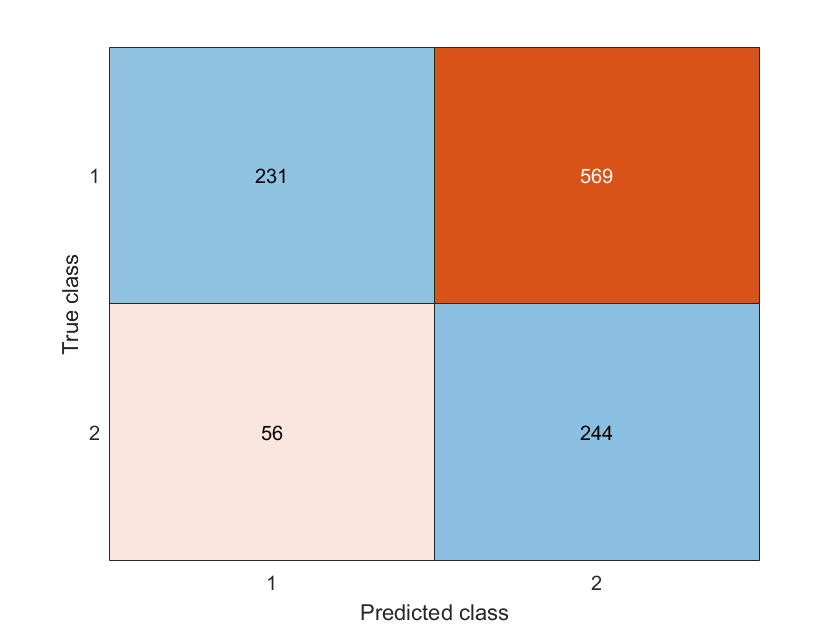

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


TP= sum(and((predictions==2)',label==2))
TN= sum(and((predictions==1)',label==1))
FP= sum(and((predictions==2)',label==1))
FN= sum(and((predictions==1)',label==2))


precision= TP/(TP+FP)
recall=TP/(TP+FN)
f1=2*(precision*recall)/(precision+recall)
specificity=FP/(FP+TN)
accuracy=(TP+TN)/(TP+TN+FP+FN)

%accuracy = sum(predictions' == label)/numel(label)

confusionchart(label,predictions)



## **7) Save the trained model**

%<---DA MODIFICARE save('filename','VariableName(trained nnet object)')




**Function that transforms a MRI picture into 100 227x227x3 images (~100MB)**

function [IMG]=mriToCNN(IMG,siz) 
    % Remove NaN values
    IMG(find(isnan(IMG)))=0;
    
    % Create 100 pictures 227x227x3
    % Resizing each 121x145 slice to 227x227
    % Exluding the first and last 10 layers because are composed most of zeros
    clear RID
    for livello=11:110
        RID(:,:,1,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
        RID(:,:,2,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
        RID(:,:,3,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
    end
    
    clear IMG
    
    % Normalize values <--------------------------------- TODO: find a better normalization
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
   
end